# Machine Learning: Programming Exercise 7

## *K*-Means Clustering and Principal Component Analysis

In this exercise, you will implement the *K*-means clustering algorithm and apply it to compress an image. In the second part, you will use principal component analysis to find a low-dimensional representation of face images.

### Files needed for this exercise

- `ex7.mlx` - MATLAB Live Script that steps you through the exercise

- `ex7data1.mat` - Example Dataset for PCA

- `ex7data2.mat` - Example Dataset for K-means

- `ex7faces.mat` - Faces Dataset

- bird small.png - Example Image

- `displayData.m` - Displays 2D data stored in a matrix

- `drawLine.m` - Draws a line over an exsiting figure

- `plotDataPoints.m` - Initialization for K-means centroids

- `plotProgresskMeans.m` - Plots each step of K-means as it proceeds

- `runkMeans.m` - Runs the K-means algorithm

- `submit.m` - Submission script that sends your solutions to our servers

- *`pca.m` - Perform principal component analysis

- *`projectData.m` - Projects a data set into a lower dimensional space

- *`recoverData.m` - Recovers the original data from the projection

- *`findClosestCentroids.m` - Find closest centroids (used in K-means)

- *`computeCentroids.m` - Compute centroid means (used in K-means)

- *`kMeansInitCentroids.m` - Initialization for K-means centroids

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex7' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       computeCentroids.m      ex7_companion.mlx       featureNormalize.m      pca.m                   recoverData.m           
..                      displayData.m           ex7data1.mat            findClosestCentroids.m  plotDataPoints.m        runkMeans.m             
bird_small.mat          drawLine.m              ex7data2.mat            kMeansInitCentroids.m   plotProgresskMeans.m    submit.m                
bird_small.png          ex7.mlx                 ex7faces.mat            lib                     projectData.m           token.mat               



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. *K*-Means Clustering

In this this exercise, you will implement the *K*-means algorithm and use it for image compression. You will first start on an example 2D dataset that will help you gain an intuition of how the *K*-means algorithm works. After that, you wil use the *K*-means algorithm for image compression by reducing the number of colors that occur in an image to only those that are most common in that image.

### 1.1 Implementing *K*-means

The K-means algorithm is a method to automatically cluster similar data examples together. Concretely, you are given a training set $\{x^{(1)},\ldots x^{(m)}\}$ (where $x^{(i)}\in \mathbb{R}^n$), and want to group the data into a few cohesive 'clusters'. The intuition behind *K*-means is an iterative procedure that starts by guessing the initial centroids, and then refines this guess by repeatedly assigning examples to their closest centroids and then recomputing the centroids based on the assignments.

    The *K*-means algorithm is as follows:

The inner-loop of the algorithm repeatedly carries out two steps: 

- Assigning each training example $x^{(i)}$ to its closest centroid

- Recomputing the mean of each centroid using the points assigned to it. 

The *K*-means algorithm will always converge to some final set of means for the centroids. Note that the converged solution may not always be ideal and depends on the initial setting of the centroids. Therefore, in practice the K-means algorithm is usually run a few times with dierent random initializations. One way to choose between these different solutions from different random initializations is to choose the one with the lowest cost function value (distortion). You will implement the two phases of the K-means algorithm separately in the next sections.

#### 1.1.1 Finding closest centroids

In the 'cluster assignment' phase of the *K*-means algorithm, the algorithm assigns every training example $x^{(i)}$ to its closest centroid, given the current positions of centroids. Specically, for every example $i$ we set 


$$c^{(i)} :=j \quad\text{that minimizes}\quad\left||x^{(i)}-\mu_j\right||^2,$$


where $c^{(i)}$ is the index of the centroid that is closest to $x^{(i)}$, and $\mu_j$ is the position (value) of the $j$-th centroid. Note that $c^{(i)}$ corresponds to `idx(i)` in the starter code.

    Your task is to complete the code in `findClosestCentroids.m`. This function takes the data matrix `X` and the locations of all centroids inside centroids and should output a one-dimensional array `idx` that holds the index (a value in $\{1,\ldots,K\}$, where $K$ is total number of centroids) of the closest centroid to every training example. You can implement this using a loop over every training example and every centroid. 

    Once you have completed the code in `findClosestCentroids.m`, the code below will run your code and you should see the output `[1 3 2]` corresponding to the centroid assignments for the first 3 examples.

% Load an example dataset that we will be using
load('ex7data2.mat');

% Select an initial set of centroids
K = 3; % 3 Centroids
initial_centroids = [3 3; 6 2; 8 5];

% Find the closest centroids for the examples using the initial_centroids
idx = findClosestCentroids(X, initial_centroids);
fprintf('Closest centroids for the first 3 examples: %d %d %d', idx(1:3))

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 1.1.2 Computing centroid means

Given assignments of every point to a centroid, the second phase of the algorithm recomputes, for each centroid, the mean of the points that were assigned to it. Specically, for every centroid $k$ we set


$$\mu_k := \frac{1}{|C_k|}\sum_{i\in C_k}{x^{(i)}}$$


where $C_k$ is the set of examples that are assigned to centroid $k$. Concretely, if two examples say $x^{(3)}$ and $x^{(5)}$ are assigned to centroid $k = 2$, then you should update $\mu_2 = \frac{1}{2} (x^{(3)} + x^{(5)})$. You should now complete the code in `computeCentroids.m`. You can implement this function using a loop over the centroids. You can also use a loop over the examples; but if you can use a vectorized implementation that does not use such a loop, your code may run faster. Once you have completed the code in `computeCentroids.m`, the code below will run your code and output the centroids after the first step of *K*-means. The centroids should be:

- `[ 2.428301 3.157924 ]`

- `[ 5.813503 2.633656 ]`

- `[ 7.119387 3.616684 ]`

% Compute means based on the closest centroids found in the previous part.
centroids = computeCentroids(X, idx, K);
fprintf('Centroids computed after initial finding of closest centroids: \n %f %f \n %f %f\n %f %f' , centroids');

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.2 K-means on example dataset

After you have completed the two functions (`findClosestCentroids` and `computeCentroids`), the code below will run the *K*-means algorithm on a toy 2D dataset to help you understand how *K*-means works. Your functions are called from inside the `runKmeans.m` script. We encourage you to take a look at the function to understand how it works. Notice that the code calls the two functions you implemented in a loop.

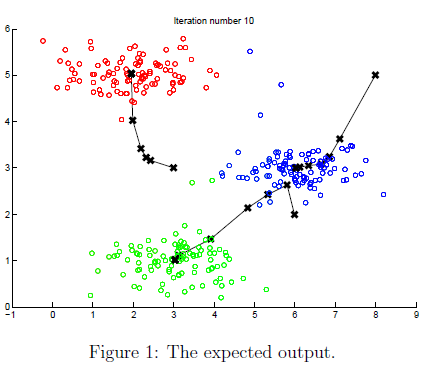

    When you run the next step, the *K*-means code will produce a visualization that steps you through the progress of the algorithm at each iteration. 

**At the command line**, **press enter multiple times to see how each step of the *****K*****-means algorithm changes the centroids and cluster assignments.** 

At the end, your figure should look as the one displayed in Figure 1.

% Load an example dataset
load('ex7data2.mat');
% Settings for running K-Means
max_iters = 10;

For consistency, here we set centroids to specific values but in practice you want to generate them automatically, such as by setting them to be random examples (as can be seen in `kMeansInitCentroids`).

initial_centroids = [3 3; 6 2; 8 5];

cost = 0

id = 0

costMin = 1.0000e+09

cost = 3.9251

costMin = 3.9251

idx =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


cost = 24.0877

cost = 38.0740

costMin = 1.0000e+09

cost = 10.3079

costMin = 10.3079

idx =      1
     1
     0
     0
     0
     0
     0
     0
     0
     0


cost = 7.9564

costMin = 7.9564

idx =      1
     2
     0
     0
     0
     0
     0
     0
     0
     0


cost = 5.5222

costMin = 5.5222

idx =      1
     3
     0
     0
     0
     0
     0
     0
     0
     0


costMin = 1.0000e+09

cost = 11.3244

costMin = 11.3244

idx =      1
     3
     1
     0
     0
     0
     0
     0
     0
     0


cost = 1.7906

costMin = 1.7906

idx =      1
     3
     2
     0
     0
     0
     0
     0
     0
     0


cost = 5.6352

costMin = 1.0000e+09

cost = 2.6084

costMin = 2.6084

idx =      1
     3
     2
     1
     0
     0
     0
     0
     0
     0


cost = 16.4087

cost = 26.1194

costMin = 1.0000e+09

cost = 3.8170

costMin = 3.8170

idx =      1
     3
     2
     1
     1
     0
     0
     0
     0
     0


cost = 16.3049

cost = 22.7376

costMin = 1.0000e+09

cost = 6.8050

costMin = 6.8050

idx =      1
     3
     2
     1
     1
     1
     0
     0
     0
     0


cost = 31.1828

cost = 45.5951

costMin = 1.0000e+09

cost = 3.1071

costMin = 3.1071

idx =      1
     3
     2
     1
     1
     1
     1
     0
     0
     0


cost = 22.1197

cost = 36.6055

costMin = 1.0000e+09

cost = 4.8109

costMin = 4.8109

idx =      1
     3
     2
     1
     1
     1
     1
     1
     0
     0


cost = 23.5146

cost = 33.2436

costMin = 1.0000e+09

cost = 3.3876

costMin = 3.3876

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     0


cost = 17.1681

cost = 25.1917

costMin = 1.0000e+09

cost = 3.2646

costMin = 3.2646

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.9998

cost = 25.2407

costMin = 1.0000e+09

cost = 6.4179

costMin = 6.4179

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 26.4756

cost = 34.7733

costMin = 1.0000e+09

cost = 5.6491

costMin = 5.6491

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 25.3360

cost = 34.5980

costMin = 1.0000e+09

cost = 5.3402

costMin = 5.3402

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 27.7941

cost = 42.1165

costMin = 1.0000e+09

cost = 5.8619

costMin = 5.8619

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 25.3919

cost = 34.0666

costMin = 1.0000e+09

cost = 10.2102

costMin = 10.2102

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 39.4653

cost = 57.4924

costMin = 1.0000e+09

cost = 3.5354

costMin = 3.5354

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.3206

cost = 30.6133

costMin = 1.0000e+09

cost = 5.1052

costMin = 5.1052

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 12.7312

cost = 15.5182

costMin = 1.0000e+09

cost = 2.8190

costMin = 2.8190

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.1344

cost = 25.0322

costMin = 1.0000e+09

cost = 8.9500

costMin = 8.9500

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 36.6958

cost = 53.7992

costMin = 1.0000e+09

cost = 3.3993

costMin = 3.3993

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.0994

cost = 23.4311

costMin = 1.0000e+09

cost = 9.8425

costMin = 9.8425

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 38.5942

cost = 56.0848

costMin = 1.0000e+09

cost = 3.8666

costMin = 3.8666

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.9845

cost = 23.6767

costMin = 1.0000e+09

cost = 7.7891

costMin = 7.7891

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 28.7389

cost = 35.7951

costMin = 1.0000e+09

cost = 10.4839

costMin = 10.4839

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 38.9769

cost = 53.8496

costMin = 1.0000e+09

cost = 7.3341

costMin = 7.3341

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 32.9196

cost = 48.7819

costMin = 1.0000e+09

cost = 5.9531

costMin = 5.9531

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 25.4746

cost = 33.9733

costMin = 1.0000e+09

cost = 5.1292

costMin = 5.1292

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.4923

cost = 26.4913

costMin = 1.0000e+09

cost = 8.1574

costMin = 8.1574

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 32.9076

cost = 44.8628

costMin = 1.0000e+09

cost = 8.0929

costMin = 8.0929

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 34.1690

cost = 49.1048

costMin = 1.0000e+09

cost = 5.0296

costMin = 5.0296

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 27.7578

cost = 43.6912

costMin = 1.0000e+09

cost = 4.9387

costMin = 4.9387

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 21.3684

cost = 28.5491

costMin = 1.0000e+09

cost = 4.5144

costMin = 4.5144

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 19.9451

cost = 27.0537

costMin = 1.0000e+09

cost = 3.7031

costMin = 3.7031

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.6527

cost = 35.2649

costMin = 1.0000e+09

cost = 6.8073

costMin = 6.8073

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.2055

cost = 22.4626

costMin = 1.0000e+09

cost = 4.7992

costMin = 4.7992

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 25.2222

cost = 37.3077

costMin = 1.0000e+09

cost = 5.3193

costMin = 5.3193

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.4883

cost = 29.6651

costMin = 1.0000e+09

cost = 6.2273

costMin = 6.2273

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 30.6634

cost = 46.9773

costMin = 1.0000e+09

cost = 6.5383

costMin = 6.5383

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 25.9192

cost = 33.2432

costMin = 1.0000e+09

cost = 4.2908

costMin = 4.2908

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.8625

cost = 33.5360

costMin = 1.0000e+09

cost = 5.3408

costMin = 5.3408

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 27.4565

cost = 41.0981

costMin = 1.0000e+09

cost = 6.8952

costMin = 6.8952

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 29.3630

cost = 40.0353

costMin = 1.0000e+09

cost = 3.8761

costMin = 3.8761

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.1791

cost = 29.2575

costMin = 1.0000e+09

cost = 6.4801

costMin = 6.4801

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.6973

cost = 27.2265

costMin = 1.0000e+09

cost = 10.8480

costMin = 10.8480

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 38.2901

cost = 49.9954

costMin = 1.0000e+09

cost = 6.3520

costMin = 6.3520

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 29.3222

cost = 42.0210

costMin = 1.0000e+09

cost = 7.8057

costMin = 7.8057

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 21.9875

cost = 23.3571

costMin = 1.0000e+09

cost = 3.4896

costMin = 3.4896

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 19.8608

cost = 29.8277

costMin = 1.0000e+09

cost = 3.6741

costMin = 3.6741

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 12.2593

cost = 17.5908

costMin = 1.0000e+09

cost = 4.2779

costMin = 4.2779

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 25.3611

cost = 40.0426

costMin = 1.0000e+09

cost = 4.1414

costMin = 4.1414

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.7978

cost = 33.9175

costMin = 1.0000e+09

cost = 5.9498

costMin = 5.9498

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 27.3125

cost = 38.2432

costMin = 1.0000e+09

cost = 4.8002

costMin = 4.8002

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 25.3928

cost = 37.7440

costMin = 1.0000e+09

cost = 5.0211

costMin = 5.0211

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 19.3172

cost = 24.7504

costMin = 1.0000e+09

cost = 4.4015

costMin = 4.4015

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 19.0353

cost = 25.7489

costMin = 1.0000e+09

cost = 5.6685

costMin = 5.6685

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 17.7406

cost = 20.9560

costMin = 1.0000e+09

cost = 3.4983

costMin = 3.4983

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 15.9948

cost = 23.0246

costMin = 1.0000e+09

cost = 11.3703

costMin = 11.3703

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 42.1980

cost = 62.4025

costMin = 1.0000e+09

cost = 6.8108

costMin = 6.8108

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 30.5076

cost = 43.4855

costMin = 1.0000e+09

cost = 4.2783

costMin = 4.2783

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.6762

cost = 33.1620

costMin = 1.0000e+09

cost = 7.7823

costMin = 7.7823

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 32.1048

cost = 44.0680

costMin = 1.0000e+09

cost = 2.7576

costMin = 2.7576

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.5987

cost = 40.5158

costMin = 1.0000e+09

cost = 7.8169

costMin = 7.8169

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 29.4593

cost = 37.3120

costMin = 1.0000e+09

cost = 4.6601

costMin = 4.6601

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 26.3397

cost = 41.0663

costMin = 1.0000e+09

cost = 11.9827

costMin = 11.9827

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 42.2288

cost = 58.1386

costMin = 1.0000e+09

cost = 2.9534

costMin = 2.9534

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 21.6507

cost = 36.0893

costMin = 1.0000e+09

cost = 8.4118

costMin = 8.4118

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 34.1073

cost = 47.3729

costMin = 1.0000e+09

cost = 3.1529

costMin = 3.1529

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.7752

cost = 32.9900

costMin = 1.0000e+09

cost = 18.0395

costMin = 18.0395

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 52.9907

cost = 68.5300

costMin = 1.0000e+09

cost = 4.8055

costMin = 4.8055

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 24.0570

cost = 34.4737

costMin = 1.0000e+09

cost = 5.4630

costMin = 5.4630

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 26.4609

cost = 37.8949

costMin = 1.0000e+09

cost = 3.5127

costMin = 3.5127

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 21.0566

cost = 32.2622

costMin = 1.0000e+09

cost = 5.7118

costMin = 5.7118

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 28.3300

cost = 41.9617

costMin = 1.0000e+09

cost = 7.9513

costMin = 7.9513

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 33.8352

cost = 48.6807

costMin = 1.0000e+09

cost = 5.3439

costMin = 5.3439

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 26.2360

cost = 37.7755

costMin = 1.0000e+09

cost = 4.4185

costMin = 4.4185

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 23.0896

cost = 33.6057

costMin = 1.0000e+09

cost = 5.7274

costMin = 5.7274

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 29.6780

cost = 46.4042

costMin = 1.0000e+09

cost = 6.5745

costMin = 6.5745

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 31.7106

cost = 48.8486

costMin = 1.0000e+09

cost = 6.5114

costMin = 6.5114

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 29.1551

cost = 40.9156

costMin = 1.0000e+09

cost = 10.9279

costMin = 10.9279

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 40.3398

cost = 56.6218

costMin = 1.0000e+09

cost = 9.9534

costMin = 9.9534

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 39.2365

cost = 58.3809

costMin = 1.0000e+09

cost = 13.7058

costMin = 13.7058

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 44.9205

cost = 59.3861

costMin = 1.0000e+09

cost = 4.5396

costMin = 4.5396

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.8351

cost = 32.6424

costMin = 1.0000e+09

cost = 6.7802

costMin = 6.7802

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 26.7783

cost = 34.3829

costMin = 1.0000e+09

cost = 4.0640

costMin = 4.0640

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 23.3058

cost = 35.4168

costMin = 1.0000e+09

cost = 9.8483

costMin = 9.8483

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.5334

cost = 9.9410

costMin = 1.0000e+09

cost = 4.6889

costMin = 4.6889

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.4335

cost = 31.3325

costMin = 1.0000e+09

cost = 5.0563

costMin = 5.0563

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.0579

cost = 29.5419

costMin = 1.0000e+09

cost = 3.9185

costMin = 3.9185

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 24.1331

cost = 38.2346

costMin = 1.0000e+09

cost = 10.1177

costMin = 10.1177

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 38.8805

cost = 55.5263

costMin = 1.0000e+09

cost = 6.7615

costMin = 6.7615

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.9242

cost = 23.6719

costMin = 1.0000e+09

cost = 4.0322

costMin = 4.0322

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 17.7952

cost = 24.5816

costMin = 1.0000e+09

cost = 4.4590

costMin = 4.4590

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.0851

cost = 31.3128

costMin = 1.0000e+09

cost = 13.2438

costMin = 13.2438

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 44.7721

cost = 61.2749

costMin = 1.0000e+09

cost = 5.0899

costMin = 5.0899

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 21.8500

cost = 29.0556

costMin = 1.0000e+09

cost = 4.3788

costMin = 4.3788

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 22.5177

cost = 32.4796

costMin = 1.0000e+09

cost = 5.2116

costMin = 5.2116

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.9542

cost = 16.7551

costMin = 1.0000e+09

cost = 5.8802

costMin = 5.8802

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 26.0078

cost = 35.3775

costMin = 1.0000e+09

cost = 6.6279

costMin = 6.6279

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 30.3438

cost = 43.8067

costMin = 1.0000e+09

cost = 6.1961

costMin = 6.1961

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 30.5862

cost = 46.8796

costMin = 1.0000e+09

cost = 7.1885

costMin = 7.1885

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 29.5399

cost = 39.4655

costMin = 1.0000e+09

cost = 5.2298

costMin = 5.2298

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.4526

cost = 41.3048

costMin = 1.0000e+09

cost = 2.0432

costMin = 2.0432

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.8155

cost = 36.1363

costMin = 1.0000e+09

cost = 4.4176

costMin = 4.4176

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.6361

cost = 30.6033

costMin = 1.0000e+09

cost = 6.2102

costMin = 6.2102

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 21.9691

cost = 58.8351

costMin = 1.0000e+09

cost = 5.6983

costMin = 5.6983

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.9524

costMin = 4.9524

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 32.3938

costMin = 1.0000e+09

cost = 4.0974

costMin = 4.0974

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.1442

cost = 39.6439

costMin = 1.0000e+09

cost = 6.8202

costMin = 6.8202

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.9647

cost = 41.5902

costMin = 1.0000e+09

cost = 5.6041

costMin = 5.6041

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.0651

cost = 34.8975

costMin = 1.0000e+09

cost = 4.7608

costMin = 4.7608

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.0101

cost = 54.6234

costMin = 1.0000e+09

cost = 8.6335

costMin = 8.6335

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.5321

costMin = 3.5321

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 29.9145

costMin = 1.0000e+09

cost = 5.0584

costMin = 5.0584

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.2890

cost = 44.2457

costMin = 1.0000e+09

cost = 7.5088

costMin = 7.5088

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 26.0247

cost = 64.1830

costMin = 1.0000e+09

cost = 5.7636

costMin = 5.7636

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.7740

cost = 57.0436

costMin = 1.0000e+09

cost = 4.3660

costMin = 4.3660

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.0315

costMin = 4.0315

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 28.9912

costMin = 1.0000e+09

cost = 2.9356

costMin = 2.9356

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.5575

cost = 37.1478

costMin = 1.0000e+09

cost = 4.4299

costMin = 4.4299

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.5109

cost = 42.3288

costMin = 1.0000e+09

cost = 1.6389

costMin = 1.6389

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.4692

cost = 32.8527

costMin = 1.0000e+09

cost = 4.9371

costMin = 4.9371

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.0884

cost = 50.8400

costMin = 1.0000e+09

cost = 3.0643

costMin = 3.0643

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.6658

cost = 35.6787

costMin = 1.0000e+09

cost = 4.3807

costMin = 4.3807

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.0331

cost = 46.1143

costMin = 1.0000e+09

cost = 3.7334

costMin = 3.7334

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.4937

cost = 38.0658

costMin = 1.0000e+09

cost = 8.0989

costMin = 8.0989

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.5905

costMin = 4.5905

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 32.6219

costMin = 1.0000e+09

cost = 3.8622

costMin = 3.8622

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.7088

cost = 34.7438

costMin = 1.0000e+09

cost = 5.9602

costMin = 5.9602

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.2378

costMin = 4.2378

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 30.7756

costMin = 1.0000e+09

cost = 7.1971

costMin = 7.1971

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.9398

costMin = 5.9398

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 35.5268

costMin = 1.0000e+09

cost = 3.6632

costMin = 3.6632

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.3013

cost = 39.4136

costMin = 1.0000e+09

cost = 7.4894

costMin = 7.4894

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 12.9405

cost = 48.9455

costMin = 1.0000e+09

cost = 3.9327

costMin = 3.9327

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.3607

cost = 34.0877

costMin = 1.0000e+09

cost = 3.9083

costMin = 3.9083

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.8192

cost = 50.0682

costMin = 1.0000e+09

cost = 4.8335

costMin = 4.8335

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.1396

cost = 43.7769

costMin = 1.0000e+09

cost = 3.7110

costMin = 3.7110

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.0754

cost = 35.3245

costMin = 1.0000e+09

cost = 3.8562

costMin = 3.8562

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.0692

cost = 35.4745

costMin = 1.0000e+09

cost = 5.1845

costMin = 5.1845

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 14.0281

cost = 48.4707

costMin = 1.0000e+09

cost = 3.9332

costMin = 3.9332

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.7649

cost = 38.7860

costMin = 1.0000e+09

cost = 5.6398

costMin = 5.6398

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.8495

cost = 44.0713

costMin = 1.0000e+09

cost = 4.2482

costMin = 4.2482

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.8900

cost = 50.7242

costMin = 1.0000e+09

cost = 3.5327

costMin = 3.5327

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 15.0710

cost = 47.4986

costMin = 1.0000e+09

cost = 4.1875

costMin = 4.1875

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 12.4966

cost = 45.1037

costMin = 1.0000e+09

cost = 5.6102

costMin = 5.6102

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.5426

costMin = 5.5426

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 33.7244

costMin = 1.0000e+09

cost = 2.3015

costMin = 2.3015

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.6677

cost = 30.3029

costMin = 1.0000e+09

cost = 7.8874

costMin = 7.8874

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.6875

costMin = 5.6875

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 35.2281

costMin = 1.0000e+09

cost = 3.0091

costMin = 3.0091

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.1925

cost = 30.3156

costMin = 1.0000e+09

cost = 3.0451

costMin = 3.0451

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.8034

cost = 35.9144

costMin = 1.0000e+09

cost = 2.7024

costMin = 2.7024

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.2449

cost = 37.9933

costMin = 1.0000e+09

cost = 2.5490

costMin = 2.5490

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.2724

cost = 36.0513

costMin = 1.0000e+09

cost = 9.1743

costMin = 9.1743

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.5712

costMin = 6.5712

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 37.6599

costMin = 1.0000e+09

cost = 3.4848

costMin = 3.4848

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.3409

cost = 37.4873

costMin = 1.0000e+09

cost = 4.7901

costMin = 4.7901

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.3189

cost = 32.5815

costMin = 1.0000e+09

cost = 3.9526

costMin = 3.9526

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.1581

cost = 41.2063

costMin = 1.0000e+09

cost = 8.4662

costMin = 8.4662

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 25.2283

cost = 65.0834

costMin = 1.0000e+09

cost = 6.3952

costMin = 6.3952

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.0653

cost = 48.2742

costMin = 1.0000e+09

cost = 5.3300

costMin = 5.3300

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.0054

cost = 42.3635

costMin = 1.0000e+09

cost = 3.8966

costMin = 3.8966

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.7010

cost = 46.3736

costMin = 1.0000e+09

cost = 3.9266

costMin = 3.9266

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.2153

cost = 41.2693

costMin = 1.0000e+09

cost = 5.0997

costMin = 5.0997

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 19.5449

cost = 54.8088

costMin = 1.0000e+09

cost = 3.4350

costMin = 3.4350

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.5428

cost = 45.4685

costMin = 1.0000e+09

cost = 6.0413

costMin = 6.0413

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 15.6341

cost = 51.6058

costMin = 1.0000e+09

cost = 4.0606

costMin = 4.0606

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.2758

cost = 43.1207

costMin = 1.0000e+09

cost = 3.5563

costMin = 3.5563

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.4062

cost = 35.8021

costMin = 1.0000e+09

cost = 5.3698

costMin = 5.3698

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.8075

cost = 38.3483

costMin = 1.0000e+09

cost = 3.2417

costMin = 3.2417

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.5488

cost = 29.0320

costMin = 1.0000e+09

cost = 3.7797

costMin = 3.7797

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.9229

cost = 30.6479

costMin = 1.0000e+09

cost = 4.6450

costMin = 4.6450

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 12.7434

cost = 46.0203

costMin = 1.0000e+09

cost = 5.7686

costMin = 5.7686

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.5906

costMin = 3.5906

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 28.9249

costMin = 1.0000e+09

cost = 3.2602

costMin = 3.2602

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.1519

cost = 38.6400

costMin = 1.0000e+09

cost = 5.6522

costMin = 5.6522

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.5423

cost = 52.3201

costMin = 1.0000e+09

cost = 7.4528

costMin = 7.4528

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 17.3208

cost = 55.2731

costMin = 1.0000e+09

cost = 4.2063

costMin = 4.2063

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 15.6085

cost = 49.2139

costMin = 1.0000e+09

cost = 5.2352

costMin = 5.2352

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 18.1837

cost = 53.6523

costMin = 1.0000e+09

cost = 7.0212

costMin = 7.0212

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.3011

costMin = 5.3011

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 33.9615

costMin = 1.0000e+09

cost = 2.5155

costMin = 2.5155

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.7888

cost = 40.1401

costMin = 1.0000e+09

cost = 4.1846

costMin = 4.1846

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.0824

cost = 31.4655

costMin = 1.0000e+09

cost = 4.2755

costMin = 4.2755

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 12.9990

cost = 45.9326

costMin = 1.0000e+09

cost = 4.9448

costMin = 4.9448

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.6380

costMin = 3.6380

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 28.4459

costMin = 1.0000e+09

cost = 3.9725

costMin = 3.9725

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.1715

cost = 37.7417

costMin = 1.0000e+09

cost = 5.5231

costMin = 5.5231

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.2058

cost = 51.7431

costMin = 1.0000e+09

cost = 6.9704

costMin = 6.9704

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.6048

cost = 39.0015

costMin = 1.0000e+09

cost = 4.8522

costMin = 4.8522

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.3405

cost = 36.9934

costMin = 1.0000e+09

cost = 5.5183

costMin = 5.5183

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 20.1067

cost = 56.0271

costMin = 1.0000e+09

cost = 6.9013

costMin = 6.9013

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 19.7685

cost = 57.6307

costMin = 1.0000e+09

cost = 5.4061

costMin = 5.4061

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.0182

cost = 42.4527

costMin = 1.0000e+09

cost = 2.8659

costMin = 2.8659

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.4898

cost = 44.4344

costMin = 1.0000e+09

cost = 3.4007

costMin = 3.4007

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 12.6252

cost = 44.1937

costMin = 1.0000e+09

cost = 3.6059

costMin = 3.6059

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.9619

cost = 32.8580

costMin = 1.0000e+09

cost = 7.2507

costMin = 7.2507

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.2897

cost = 44.2983

costMin = 1.0000e+09

cost = 5.6139

costMin = 5.6139

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.6159

cost = 33.8948

costMin = 1.0000e+09

cost = 2.6825

costMin = 2.6825

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.8625

cost = 35.5022

costMin = 1.0000e+09

cost = 5.2847

costMin = 5.2847

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.6710

costMin = 3.6710

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 28.8086

costMin = 1.0000e+09

cost = 7.1035

costMin = 7.1035

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.7004

cost = 49.8397

costMin = 1.0000e+09

cost = 2.9720

costMin = 2.9720

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.7753

cost = 37.5857

costMin = 1.0000e+09

cost = 3.8911

costMin = 3.8911

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.2899

cost = 41.3486

costMin = 1.0000e+09

cost = 2.7935

costMin = 2.7935

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.7466

cost = 37.2744

costMin = 1.0000e+09

cost = 7.4675

costMin = 7.4675

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 18.2214

cost = 56.4408

costMin = 1.0000e+09

cost = 3.3232

costMin = 3.3232

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.1639

cost = 32.9572

costMin = 1.0000e+09

cost = 4.8847

costMin = 4.8847

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 14.0427

cost = 48.1381

costMin = 1.0000e+09

cost = 4.2779

costMin = 4.2779

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 15.9871

cost = 49.7658

costMin = 1.0000e+09

cost = 12.1786

costMin = 12.1786

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.1617

costMin = 3.1617

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 28.7798

costMin = 1.0000e+09

cost = 4.2170

costMin = 4.2170

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.1148

cost = 49.8173

costMin = 1.0000e+09

cost = 11.8068

costMin = 11.8068

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 28.6198

cost = 72.3636

costMin = 1.0000e+09

cost = 3.6753

costMin = 3.6753

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.4420

cost = 42.8812

costMin = 1.0000e+09

cost = 9.1045

costMin = 9.1045

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5298

costMin = 0.5298

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.1425

costMin = 1.0000e+09

cost = 9.3476

costMin = 9.3476

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.9052

costMin = 0.9052

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.9791

costMin = 1.0000e+09

cost = 14.2597

costMin = 14.2597

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.0672

costMin = 2.0672

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.7020

costMin = 1.0000e+09

cost = 7.0652

costMin = 7.0652

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.6108

costMin = 0.6108

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.8863

costMin = 1.0000e+09

cost = 6.9341

costMin = 6.9341

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.1146

costMin = 1.1146

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.6415

costMin = 1.0000e+09

cost = 10.1613

costMin = 10.1613

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.6952

costMin = 1.6952

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.2559

costMin = 1.0000e+09

cost = 18.0375

costMin = 18.0375

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.4934

costMin = 2.4934

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.6930

costMin = 1.0000e+09

cost = 6.7771

costMin = 6.7771

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.9575

costMin = 1.9575

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.6204

costMin = 1.0000e+09

cost = 5.6040

costMin = 5.6040

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.7213

costMin = 1.7213

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.3895

costMin = 1.0000e+09

cost = 2.9618

costMin = 2.9618

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.2894

costMin = 2.2894

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 15.7357

costMin = 1.0000e+09

cost = 19.8332

costMin = 19.8332

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.1933

costMin = 4.1933

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.6768

costMin = 2.6768

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


costMin = 1.0000e+09

cost = 13.2610

costMin = 13.2610

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.5345

costMin = 1.5345

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.6103

costMin = 1.0000e+09

cost = 11.5802

costMin = 11.5802

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.4569

costMin = 0.4569

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.5827

costMin = 1.0000e+09

cost = 18.4469

costMin = 18.4469

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.2236

costMin = 2.2236

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.5616

costMin = 1.0000e+09

cost = 10.3622

costMin = 10.3622

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5016

costMin = 0.5016

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.6185

costMin = 1.0000e+09

cost = 6.2362

costMin = 6.2362

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.4468

costMin = 0.4468

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 14.2931

costMin = 1.0000e+09

cost = 7.1158

costMin = 7.1158

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.0415

costMin = 1.0415

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.5836

costMin = 1.0000e+09

cost = 12.9436

costMin = 12.9436

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.5031

costMin = 1.5031

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.6901

costMin = 1.0000e+09

cost = 22.6496

costMin = 22.6496

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.4221

costMin = 4.4221

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.4594

costMin = 3.4594

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


costMin = 1.0000e+09

cost = 13.2179

costMin = 13.2179

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.7181

costMin = 1.7181

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.2996

costMin = 1.0000e+09

cost = 7.6731

costMin = 7.6731

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.3604

costMin = 1.3604

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.4387

costMin = 1.0000e+09

cost = 9.0244

costMin = 9.0244

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5732

costMin = 0.5732

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.0538

costMin = 1.0000e+09

cost = 11.5380

costMin = 11.5380

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5662

costMin = 0.5662

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.1501

costMin = 1.0000e+09

cost = 7.5204

costMin = 7.5204

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.2860

costMin = 1.2860

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.7011

costMin = 1.0000e+09

cost = 2.6559

costMin = 2.6559

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.5432

costMin = 2.5432

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.3178

costMin = 1.0000e+09

cost = 5.4554

costMin = 5.4554

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.5219

costMin = 1.5219

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.9448

costMin = 1.0000e+09

cost = 5.6644

costMin = 5.6644

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.0604

costMin = 1.0604

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.6676

costMin = 1.0000e+09

cost = 4.1514

costMin = 4.1514

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.7844

costMin = 1.7844

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.0908

costMin = 1.0000e+09

cost = 6.5097

costMin = 6.5097

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.0088

costMin = 2.0088

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.8716

costMin = 1.0000e+09

cost = 9.3450

costMin = 9.3450

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.6539

costMin = 0.6539

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.6082

costMin = 1.0000e+09

cost = 5.1885

costMin = 5.1885

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.7927

costMin = 0.7927

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 16.0759

costMin = 1.0000e+09

cost = 7.4835

costMin = 7.4835

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.8412

costMin = 0.8412

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.6455

costMin = 1.0000e+09

cost = 14.3000

costMin = 14.3000

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.7269

costMin = 1.7269

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.2618

costMin = 1.0000e+09

cost = 12.0157

costMin = 12.0157

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.0316

costMin = 2.0316

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.1203

costMin = 1.0000e+09

cost = 11.5665

costMin = 11.5665

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.9652

costMin = 0.9652

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.9821

costMin = 1.0000e+09

cost = 8.1835

costMin = 8.1835

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.0110

costMin = 1.0110

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.5936

costMin = 1.0000e+09

cost = 11.9137

costMin = 11.9137

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.5590

costMin = 1.5590

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.7748

costMin = 1.0000e+09

cost = 5.6411

costMin = 5.6411

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.8287

costMin = 1.8287

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.1902

costMin = 1.0000e+09

cost = 8.4566

costMin = 8.4566

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.8248

costMin = 1.8248

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.1985

costMin = 1.0000e+09

cost = 1.0030

costMin = 1.0030

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.6737

cost = 21.5057

costMin = 1.0000e+09

cost = 10.8173

costMin = 10.8173

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.4582

costMin = 1.4582

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.2791

costMin = 1.0000e+09

cost = 1.4878

costMin = 1.4878

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.8856

cost = 19.1634

costMin = 1.0000e+09

cost = 5.4121

costMin = 5.4121

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.5214

costMin = 1.5214

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.0180

costMin = 1.0000e+09

cost = 17.5701

costMin = 17.5701

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.3666

costMin = 3.3666

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.2075

costMin = 3.2075

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


costMin = 1.0000e+09

cost = 20.2299

costMin = 20.2299

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.9407

costMin = 2.9407

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.9199

costMin = 1.0000e+09

cost = 19.5781

costMin = 19.5781

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.1594

costMin = 4.1594

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.6579

costMin = 2.6579

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


costMin = 1.0000e+09

cost = 4.0981

costMin = 4.0981

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.9258

costMin = 1.9258

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 12.9075

costMin = 1.0000e+09

cost = 5.4024

costMin = 5.4024

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.1345

costMin = 1.1345

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.9615

costMin = 1.0000e+09

cost = 8.3215

costMin = 8.3215

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.4954

costMin = 1.4954

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.6895

costMin = 1.0000e+09

cost = 9.3277

costMin = 9.3277

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.4680

costMin = 0.4680

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.2192

costMin = 1.0000e+09

cost = 8.5051

costMin = 8.5051

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.7409

costMin = 0.7409

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.9518

costMin = 1.0000e+09

cost = 13.6614

costMin = 13.6614

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.2754

costMin = 1.2754

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.1540

costMin = 1.0000e+09

cost = 9.1374

costMin = 9.1374

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5243

costMin = 0.5243

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.1395

costMin = 1.0000e+09

cost = 15.4629

costMin = 15.4629

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.2988

costMin = 2.2988

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.3923

costMin = 1.0000e+09

cost = 11.2215

costMin = 11.2215

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.8252

costMin = 1.8252

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.6309

costMin = 1.0000e+09

cost = 10.5576

costMin = 10.5576

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.6858

costMin = 0.6858

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.9647

costMin = 1.0000e+09

cost = 6.7081

costMin = 6.7081

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.7346

costMin = 1.7346

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.9362

costMin = 1.0000e+09

cost = 11.7180

costMin = 11.7180

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.6226

costMin = 0.6226

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.9384

costMin = 1.0000e+09

cost = 14.4731

costMin = 14.4731

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.0230

costMin = 2.0230

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.7670

costMin = 1.0000e+09

cost = 17.8552

costMin = 17.8552

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.0121

costMin = 2.0121

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.7709

costMin = 1.0000e+09

cost = 12.4015

costMin = 12.4015

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.7901

costMin = 0.7901

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.3822

costMin = 1.0000e+09

cost = 2.6888

costMin = 2.6888

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.7098

cost = 14.3079

costMin = 1.0000e+09

cost = 21.6860

costMin = 21.6860

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.4977

costMin = 3.4977

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.6518

costMin = 1.0000e+09

cost = 6.4023

costMin = 6.4023

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.6430

costMin = 0.6430

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.8557

costMin = 1.0000e+09

cost = 13.1815

costMin = 13.1815

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.4279

costMin = 1.4279

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.8154

costMin = 1.0000e+09

cost = 0.3103

costMin = 0.3103

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.9242

cost = 25.9784

costMin = 1.0000e+09

cost = 27.4153

costMin = 27.4153

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.0288

costMin = 5.0288

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.7136

costMin = 1.0000e+09

cost = 3.8395

costMin = 3.8395

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.8943

costMin = 1.8943

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.6805

costMin = 1.0000e+09

cost = 5.9224

costMin = 5.9224

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5983

costMin = 0.5983

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.4189

costMin = 1.0000e+09

cost = 7.2816

costMin = 7.2816

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.9933

costMin = 0.9933

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.5027

costMin = 1.0000e+09

cost = 11.2912

costMin = 11.2912

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.1338

costMin = 0.1338

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 10.5834

costMin = 1.0000e+09

cost = 4.2729

costMin = 4.2729

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.4702

costMin = 1.4702

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 13.7177

costMin = 1.0000e+09

cost = 15.1115

costMin = 15.1115

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.5739

costMin = 1.5739

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.7002

costMin = 1.0000e+09

cost = 1.4222

costMin = 1.4222

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.0814

cost = 18.9734

costMin = 1.0000e+09

cost = 8.8519

costMin = 8.8519

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.0531

costMin = 1.0531

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.9972

costMin = 1.0000e+09

cost = 9.7218

costMin = 9.7218

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.3917

costMin = 0.3917

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.3013

costMin = 1.0000e+09

cost = 7.4219

costMin = 7.4219

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.1673

costMin = 1.1673

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.0042

costMin = 1.0000e+09

cost = 1.8868

costMin = 1.8868

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.7615

cost = 16.9423

costMin = 1.0000e+09

cost = 10.8880

costMin = 10.8880

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.6871

costMin = 0.6871

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.8644

costMin = 1.0000e+09

cost = 5.8844

costMin = 5.8844

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.2770

costMin = 5.2770

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.9021

costMin = 1.0000e+09

cost = 13.0077

costMin = 13.0077

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 2.2355

costMin = 2.2355

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 4.6368

costMin = 1.0000e+09

cost = 7.8568

costMin = 7.8568

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.7158

costMin = 1.7158

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.8097

costMin = 1.0000e+09

cost = 13.8979

costMin = 13.8979

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.5388

costMin = 1.5388

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 5.6005

costMin = 1.0000e+09

cost = 13.6026

costMin = 13.6026

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5793

costMin = 0.5793

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.5520

costMin = 1.0000e+09

cost = 10.5214

costMin = 10.5214

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5847

costMin = 0.5847

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.2845

costMin = 1.0000e+09

cost = 10.3899

costMin = 10.3899

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.7034

costMin = 0.7034

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.9728

costMin = 1.0000e+09

cost = 7.7412

costMin = 7.7412

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.2140

costMin = 1.2140

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.6101

costMin = 1.0000e+09

cost = 13.2021

costMin = 13.2021

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.9443

costMin = 0.9443

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 6.9792

costMin = 1.0000e+09

cost = 4.8269

costMin = 4.8269

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.7909

costMin = 1.7909

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.5889

costMin = 1.0000e+09

cost = 8.3122

costMin = 8.3122

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.5919

costMin = 1.5919

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 7.5738

costMin = 1.0000e+09

cost = 8.3949

costMin = 8.3949

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.8181

costMin = 0.8181

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.8450

costMin = 1.0000e+09

cost = 7.0135

costMin = 7.0135

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5033

costMin = 0.5033

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 11.4481

costMin = 1.0000e+09

cost = 6.9284

costMin = 6.9284

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.2330

costMin = 1.2330

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.4205

costMin = 1.0000e+09

cost = 6.2770

costMin = 6.2770

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 1.4989

costMin = 1.4989

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 9.7764

costMin = 1.0000e+09

cost = 12.3269

costMin = 12.3269

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 0.5359

costMin = 0.5359

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 8.3023

costMin = 1.0000e+09

cost = 18.6585

costMin = 18.6585

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


cost = 3.6021

costMin = 3.6021

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1



% Run K-Means algorithm. The 'true' at the end tells our function to plot the progress of K-Means
figure('visible','on'); hold on; 
plotProgresskMeans(X, initial_centroids, initial_centroids, idx, K, 1); 
xlabel('Press ENTER in command window to advance','FontWeight','bold','FontSize',14)
[~, ~] = runkMeans(X, initial_centroids, max_iters, true);
set(gcf,'visible','off'); hold off;

### 1.3 Random initialization

The initial assignments of centroids for the example dataset were designed so that you will see the same figure as in Figure 1. In practice, a good strategy for initializing the centroids is to select random examples from the training set. In this part of the exercise, you should complete the function `kMeansInitCentroids.m` with the following code:

The code above first randomly permutes the indices of the examples (using randperm). Then, it selects the first $K$ examples based on the random permutation of the indices. This allows the examples to be selected at random without the risk of selecting the same example twice.

*You do not need to make any submissions for this part of the exercise.*

### 1.4 Image compression with *K*-means

In this exercise, you will apply *K*-means to image compression. In a straightforward 24-bit color representation of an image, each pixel is represented as three 8-bit unsigned integers (ranging from 0 to 255) that specify the red, green and blue intensity values. This encoding is often refered to as the RGB encoding. Our image contains thousands of colors, and in this part of the exercise, you will reduce the number of colors to 16 colors. By making this reduction, it is possible to represent (compress) the photo in an efficient way. Specifically, you only need to store the RGB values of the 16 selected colors, and for each pixel in the image you now need to only store the index of the color at that location (where only 4 bits are necessary to represent 16 possibilities). 

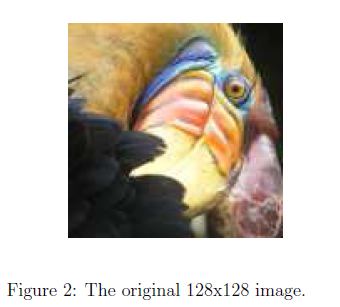

    In this exercise, you will use the *K*-means algorithm to select the 16 colors that will be used to represent the compressed image. Concretely, you will treat every pixel in the original image as a data example and use the *K*-means algorithm to find the 16 colors that best group (cluster) the pixels in the 3-dimensional RGB space. Once you have computed the cluster centroids on the image, you will then use the 16 colors to replace the pixels in the original image.

**The provided photo used in this exercise belongs to Frank Wouters and is used with his permission.*

#### 1.4.1 *K*-means on pixels

In MATLAB, images can be read in as follows:

This creates a three-dimensional matrix `A` whose first two indices identify a pixel position and whose last index represents red, green, or blue. For example, `A(50,33,3)` gives the blue intensity of the pixel at row 50 and column 33. The code below first loads the image, and then reshapes it to create an m by 3 matrix of pixel colors (where $m = 16384 = 128\times128$), and calls your *K*-means function on it.

%  Load an image of a bird
A = double(imread('bird_small.png'));
A = A / 255; % Divide by 255 so that all values are in the range 0 - 1

% Size of the image
img_size = size(A);

Reshape the image into an Nx3 matrix where N = number of pixels. Each row will contain the Red, Green and Blue pixel values. This gives us our dataset matrix X that we will use K-Means on.

X = reshape(A, img_size(1) * img_size(2), 3);

Run your K-Means algorithm on this data. You should try different values of K and max_iters here:

K = 16;
max_iters = 10;

When using K-Means, it is important the initialize the centroids randomly. You should complete the code in `kMeansInitCentroids.m` before proceeding

initial_centroids = kMeansInitCentroids(X, K);
% Run K-Means
[centroids, ~] = runkMeans(X, initial_centroids, max_iters);

    After finding the top $K = 16$ colors to represent the image, you can now assign each pixel position to its closest centroid using the `findClosestCentroids` function. This allows you to represent the original image using the centroid assignments of each pixel. Notice that you have signicantly reduced the number of bits that are required to describe the image. The original image required 24 bits for each one of the $128\times128$ pixel locations, resulting in total size of $128\times128\times24 = 393,216$ bits. 

    The new representation requires some overhead storage in form of a dictionary of 16 colors, each of which require 24 bits, but the image itself then only requires 4 bits per pixel location. The final number of bits used is therefore $16\times24 + 128\times128\times4 = 65,920$ bits, which corresponds to compressing the original image by about a factor of 6. 

% Find closest cluster members
idx = findClosestCentroids(X, centroids);

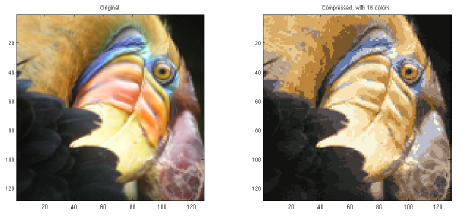

    Finally, you can view the effects of the compression by reconstructing the image based only on the centroid assignments. Specically, you can replace each pixel location with the mean of the centroid assigned to it. Figure 3 shows the reconstruction we obtained. Even though the resulting image retains most of the characteristics of the original, we also see some compression artifacts.

Essentially, now we have represented the image `X` as in terms of the indices in `idx`. We can now recover the image from the indices (`idx`) by mapping each pixel (specified by it's index in `idx`) to the centroid value.

X_recovered = centroids(idx,:);

% Reshape the recovered image into proper dimensions
X_recovered = reshape(X_recovered, img_size(1), img_size(2), 3);

% Display the original image 
figure;
subplot(1, 2, 1);
imagesc(A); 
title('Original');
axis square

% Display compressed image side by side
subplot(1, 2, 2);
imagesc(X_recovered)
title(sprintf('Compressed, with %d colors.', K));
axis square

*You do not need to make any submissions for this part of the exercise.*

### 1.5 Optional (ungraded) exercise: Use your own image

In this exercise, modify the code we have supplied to run on one of your own images. Note that if your image is very large, then *K*-means can take a long time to run. Therefore, we recommend that you resize your images to managable sizes before running the code. You can also try to vary `K` to see the effects on the compression.

## 2. Principal Component Analysis

In this exercise, you will use principal component analysis (PCA) to perform dimensionalty reduction. You will first experiment with an example 2D dataset to get intuition on how PCA works, and then use it on a bigger dataset of 5000 face image dataset. The code provided, will help you step through the first half of the exercise.

### 2.1 Example dataset

To help you understand how PCA works, you will first start with a 2D dataset which has one direction of large variation and one of smaller variation. The code below will plot the training data (Figure 4). 

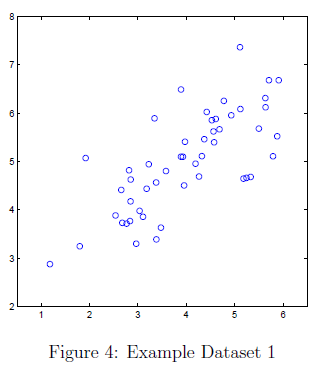

In this part of the exercise, you will visualize what happens when you use PCA to reduce the data from 2D to 1D. In practice, you might want to reduce data from 256 to 50 dimensions, say; but using lower dimensional data in this example allows us to visualize the algorithms better.

% Initialization
clear;
% The following command loads the dataset. You should now have the variable X in your environment
load ('ex7data1.mat');

% Visualize the example dataset
figure;
plot(X(:, 1), X(:, 2), 'bo');
axis([0.5 6.5 2 8]); axis square;

### 2.2 Implementing PCA

In this part of the exercise, you will implement PCA. PCA consists of two computational steps: First, you compute the covariance matrix of the data. Then, you use MATLAB's `svd` function to compute the eigenvectors $U_1, U_2,\ldots,U_n$. These will correspond to the principal components of variation in the data. Before using PCA, it is important to first normalize the data by subtracting the mean value of each feature from the dataset, and scaling each dimension so that they are in the same range. In the code below, this normalization has been performed for you using the `featureNormalize` function.

    After normalizing the data, you can run PCA to compute the principal components. You task is to complete the code in `pca.m` to compute the principal components of the dataset. First, you should compute the covariance matrix of the data, which is given by:


$$\Sigma =\frac{1}{m}X^T X$$


where $X$ is the data matrix with examples in rows, and $m$ is the number of examples. Note that $\Sigma$ is a $n \times n$ matrix and not the summation operator.

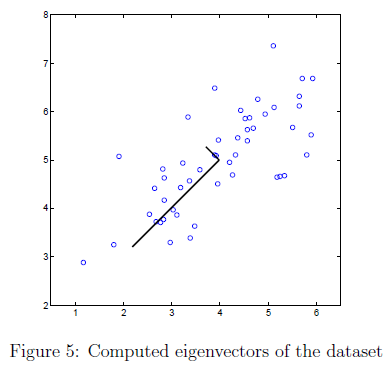

After computing the covariance matrix, you can run SVD on it to compute the principal components. In MATLAB, you can run SVD with the following command: 

where `U` will contain the principal components and `S` will contain a diagonal matrix. Once you have completed `pca.m`, the code below will run PCA on the example dataset and plot the corresponding principal components found (Figure 5). The script will also output the top principal component (eigenvector) found, and you should expect to see an output of about `[-0.707 -0.707]`. (It is possible that MATLAB may instead output the negative of this, since $U_1$ and $-U_1$ are equally valid choices for the first principal component.)

% Before running PCA, it is important to first normalize X
[X_norm, mu, ~] = featureNormalize(X);

% Run PCA
[U, S] = pca(X_norm);

% Draw the eigenvectors centered at mean of data. These lines show the directions of maximum variations in the dataset.
hold on;
drawLine(mu, mu + 1.5 * S(1,1) * U(:,1)', '-k', 'LineWidth', 2);
drawLine(mu, mu + 1.5 * S(2,2) * U(:,2)', '-k', 'LineWidth', 2);
hold off;

fprintf('Top eigenvector U(:,1) = %f %f \n', U(1,1), U(2,1));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 2.3 Dimensionality reduction with PCA

After computing the principal components, you can use them to reduce the feature dimension of your dataset by projecting each example onto a lower dimensional space, $x^{(i)}\rightarrow z^{(i)}$ (e.g., projecting the data from 2D to 1D). In this part of the exercise, you will use the eigenvectors returned by PCA and project the example dataset into a 1-dimensional space.

    In practice, if you were using a learning algorithm such as linear regression or perhaps neural networks, you could now use the projected data instead of the original data. By using the projected data, you can train your model faster as there are less dimensions in the input.

#### 2.3.1 Projecting the data onto the principal components

You should now complete the code in `projectData.m`. Specically, you are given a dataset `X`, the principal components `U`, and the desired number of dimensions to reduce to `K`. You should project each example in `X` onto the top `K` components in `U`. Note that the top `K` components in `U` are given by the first `K` columns of `U`, that is `U_reduce = U(:, 1:K)`.

Once you have completed the code in` projectData.m`, run the code below to project the first example onto the first dimension and you should see a value of about `1.481` (or possibly `-1.481`, if you got $-U_1$ instead of $U_1$).

% Project the data onto K = 1 dimension
K = 1;
Z = projectData(X_norm, U, K);
fprintf('Projection of the first example: %f\n', Z(1));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.2 Reconstructing an approximation of the data

After projecting the data onto the lower dimensional space, you can approximately recover the data by projecting them back onto the original high dimensional space. Your task is to complete `recoverData.m` to project each example in `Z` back onto the original space and return the recovered approximation in `X_rec`. Once you have completed the code in `recoverData.m`, the code below will recover an approximation of the first example and you should see a value of about `[-1.047 -1.047]`.

X_rec  = recoverData(Z, U, K);
fprintf('Approximation of the first example: %f %f\n', X_rec(1, 1), X_rec(1, 2));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.3 Visualizing the projections

After completing both `projectData` and `recoverData`, the code in this section will perform both the projection and approximate reconstruction to show how the projection affects the data. In Figure 6, the original data points are indicated with the blue circles, while the projected data points are indicated with the red circles. The projection effectively only retains the information in the direction given by $U_1$.

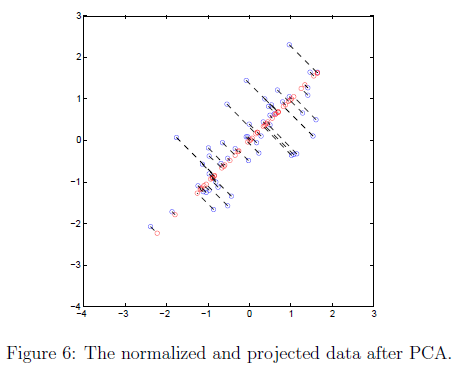

%  Plot the normalized dataset (returned from pca)
plot(X_norm(:, 1), X_norm(:, 2), 'bo');
axis([-4 3 -4 3]); axis square
%  Draw lines connecting the projected points to the original points
hold on;
plot(X_rec(:, 1), X_rec(:, 2), 'ro');
for i = 1:size(X_norm, 1)
    drawLine(X_norm(i,:), X_rec(i,:), '--k', 'LineWidth', 1);
end
hold off

### 2.4 Face image dataset

In this part of the exercise, you will run PCA on face images to see how it can be used in practice for dimension reduction. The dataset `ex7faces.mat` contains a dataset* `X` of face images, each $32 \times 32$ in grayscale. 

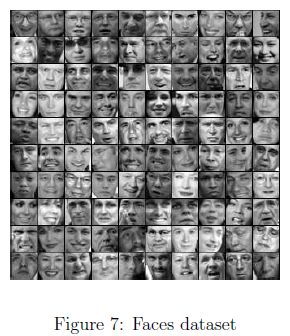

Each row of `X` corresponds to one face image (a row vector of length 1024). The code in this section will load and visualize the first 100 of these face images (Figure 7).

%  Load Face dataset
load ('ex7faces.mat')
%  Display the first 100 faces in the dataset
close all;
displayData(X(1:100, :));

**This dataset was based on a cropped version of the*[ *labeled faces in the wild dataset*](http://vis-www.cs.umass.edu/lfw/)*.*

#### 2.4.1 PCA on faces

To run PCA on the face dataset, we first normalize the dataset by subtracting the mean of each feature from the data matrix `X`. The code below will do this for you and then run your PCA code. After running PCA, you will obtain the principal components of the dataset. Notice that each principal component in `U` (each row) is a vector of length $n$ (where for the face dataset, $n = 1024$). It turns out that we can visualize these principal components by reshaping each of them into a $32 \times 32$ matrix that corresponds to the pixels in the original dataset. 

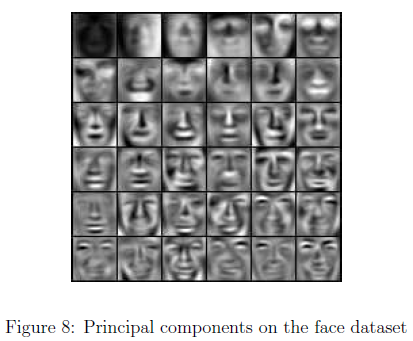

The code below displays the first 36 principal components that describe the largest variations (Figure 8).  If you want, you can also change the code to display more principal components to see how they capture more and more details. Before running PCA, it is important to first normalize `X` by subtracting the mean value from each feature.

[X_norm, ~, ~] = featureNormalize(X);

% Run PCA
[U, ~] = pca(X_norm);

% Visualize the top 36 eigenvectors found
displayData(U(:, 1:36)');

The code below will project the face dataset onto only the first 100 principal components. Concretely, each face image is now described by a vector $z^{(i)}\in\mathbb{R}^{100}$. 

K = 100;
Z = projectData(X_norm, U, K);

fprintf('The projected data Z has a size of: %d x %d', size(Z));

To understand what is lost in the dimension reduction, you can recover the data using only the projected dataset. In the code below, an approximate recovery of the data is performed and the original and projected face images are displayed side by side (Figure 9). 

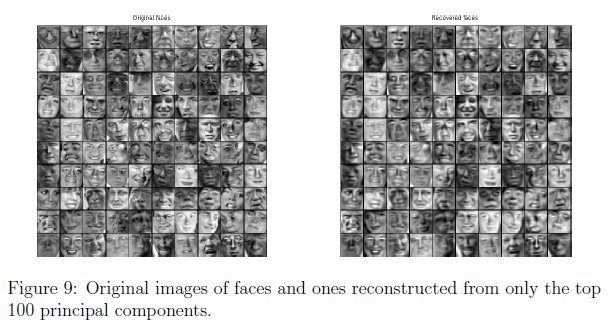

From the reconstruction, you can observe that the general structure and appearance of the face are kept while the fine details are lost. This is a remarkable reduction (more than $10\times$) in the dataset size that can help speed up your learning algorithm signicantly. For example, if you were training a neural network to perform person recognition (gven a face image, predict the identitfy of the person), you can use the dimension reduced input of only a 100 dimensions instead of the original pixels.

X_rec  = recoverData(Z, U, K);

% Display normalized data
subplot(1, 2, 1);
displayData(X_norm(1:100,:));
title('Original faces');
axis square;

% Display reconstructed data from only k eigenfaces
subplot(1, 2, 2);
displayData(X_rec(1:100,:));
title('Recovered faces');
axis square;

### 2.5 Optional (ungraded) exercise: PCA for visualization

In the earlier *K*-means image compression exercise, you used the *K*-means algorithm in the 3-dimensional RGB space. In this section, we have provided code to visualize the final pixel assignments in this 3D space using the `scatter3` function. Each data point is colored according to the cluster it has been assigned to. You can select the rotate icon and then drag your mouse on the figure to rotate and inspect this data in 3 dimensions.

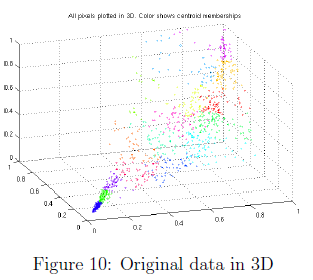

clear;
% Re-load the image from the previous exercise and run K-Means on it
% For this to work, you need to complete the K-Means assignment first
A = double(imread('bird_small.png'));
A = A / 255;
img_size = size(A);
X = reshape(A, img_size(1) * img_size(2), 3);
K = 16; 
max_iters = 10;
initial_centroids = kMeansInitCentroids(X, K);
[centroids, idx] = runkMeans(X, initial_centroids, max_iters);

%  Sample 1000 random indexes (since working with all the data is
%  too expensive. If you have a fast computer, you may increase this.
sel = floor(rand(1000, 1) * size(X, 1)) + 1;

%  Setup Color Palette
palette = hsv(K);
colors = palette(idx(sel), :);

%  Visualize the data and centroid memberships in 3D
figure;
scatter3(X(sel, 1), X(sel, 2), X(sel, 3), 10, colors);
title('Pixel dataset plotted in 3D. Color shows centroid memberships');

    It turns out that visualizing datasets in 3 dimensions or greater can be cumbersome. Therefore, it is often desirable to only display the data in 2D even at the cost of losing some information. In practice, PCA is often used to reduce the dimensionality of data for visualization purposes. In the code below, the script will apply your implementation of PCA to the 3-dimensional data to reduce it to 2 dimensions and visualize the result in a 2D scatter plot. The PCA projection can be thought of as a rotation that selects the view that maximizes the spread of the data, which often corresponds to the 'best' view.

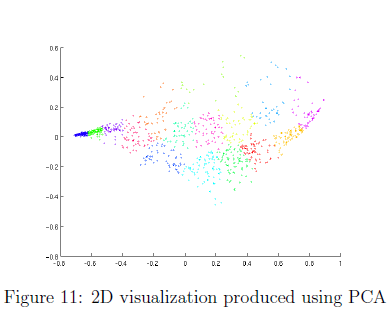

% Subtract the mean to use PCA
[X_norm, mu, sigma] = featureNormalize(X);

% PCA and project the data to 2D
[U, S] = pca(X_norm);
Z = projectData(X_norm, U, 2);

% Plot in 2D
figure;
plotDataPoints(Z(sel, :), idx(sel), K);
title('Pixel dataset plotted in 2D, using PCA for dimensionality reduction');

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored. 

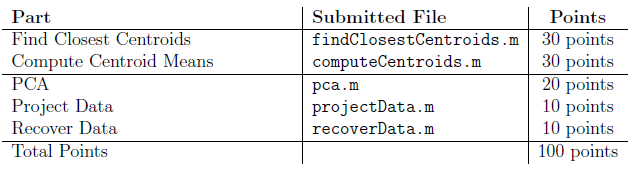

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.